# Analysis of Damage Caused by Hurricane Harvey and Recommendation for Resource Allocation

## **Table of Contents**

Background and Scope

Visualizations

Analysis

Conclusions and Recommendations

## Background and Scope

In 2017, Hurricane Harvey became one of the costliest hurricanes on record, causing approximately $125 billion in damage. Most of the damage was caused from flooding with some areas receiving over 40 inches (102 cm) of rain.

Hurricanes are large weather events with a specific definition – a rotating low-pressure weather system with sustained winds of 74+ mph (119 km/h). Harvey became a hurricane August 24th, made landfall on the 25th, and was downgraded to a tropical storm on August 26th. Harvey related events were reported beginning August 17th and ended September 3rd as the system moved north and east across the United States. Flooding, thunderstorms, hail, and tornadoes were just a few of the weather events related to Harvey. 

In the aftermath of a large-scale weather event, we saw a temporary surge in the number of claims received by insurance companies. This project aims to help the insurance company decide where to send the contractors in the aftermath of Hurricane Harvey. Below is a table generated by a predictive model to estimate the damage caused by Hurricane Harvey. My analysis will be majorly based on this data.

### Import the Data

filename = "StormEvents_2017_finalProject.csv";
Events = importfile(filename);
month = ["January","February","March","April","May","June","July","August","September","October","November","December"];
Events.Month = reordercats(Events.Month,month);
Events.Property_Cost(ismissing(Events.Property_Cost)) = 0;
Events.Crop_Cost(ismissing(Events.Crop_Cost)) = 0;
Events = Events(Events.Begin_Date_Time >= '2017-08-17 00:00:00' & Events.Begin_Date_Time < '2017-09-03 23:23:01' | ismissing(Events.Begin_Date_Time),:)

Events = 2248×24 table
    EpisodeID      Event_ID      State      Year    Month        Event_Type           CZ_Name          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                   

### Two States Most Impacted by Harvey

Identifying the most impacted states is the first step for the exploration. By looking for states that endured the most signifcant total property cost, which included both property cost and crop cost, several states manifested themselves, such as Texas, Puerto Rico, Florida.

However, it is important to gather data from multiple sources and learn about the event. Context can often help us determine if the results are reasonable, especially when our estimation for the costs was primarily based on predictive modeling. By searching for existing information, seven states had been seen to be heavily impacted - Arkansas, Kentucky, Louisiana, Mississippi, North Carolina, Tennessee, and Texas.

Combining the two sources of information, the most two states most impacted by Harvey should be Texas and Louisiana.

A = groupsummary(Events,"State",'sum','Property_Cost');
A = sortrows(A,'sum_Property_Cost','descend')

A = 57×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                275           7.7427e+10    
    LOUISIANA             86           7.5277e+07    
    NORTH CAROLINA        59           1.2338e+07    
    WASHINGTON             5                4e+06    
    FLORIDA               68            2.237e+06    
    MINNESOTA             24            1.375e+06    
    NEBRASKA              62            1.054e+06    
    MISSISSIPPI           39             9.15e+05    
    NEW YORK             116             6.41e+05    
    TENNESSEE             46             5.04e+05    
    PENNSYLVANIA         203           4.9163e+05    
    KENTUCKY              21             4.35e+05    
    CALIFORNIA            82             3.29e+05    
    IOWA                  68             3.21e+05    
    INDIANA       

### Table of Events for Two Most Impacted States

Below is a table containing only events from the two states identified above.

MostImpacted = Events(Events.State == "TEXAS" | Events.State == "LOUISIANA",:)

MostImpacted = 361×24 table
    EpisodeID      Event_ID     State    Year    Month        Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                    

## Visualizations

### Figure of Event Types

As shown below, the three most frequent event types are hail, thunderstorm wind, and flash flood.

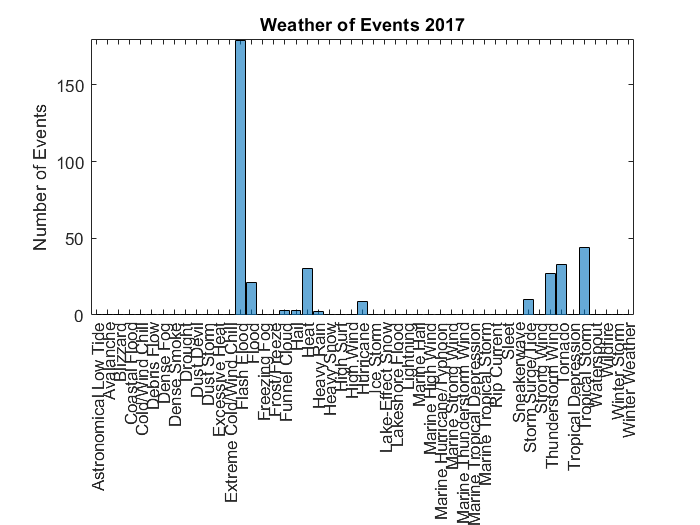

histogram (MostImpacted.Event_Type)
title('Weather of Events 2017')
ylabel('Number of Events')

### Figure of Event Locations

The following figure shows the location of events in the two states.

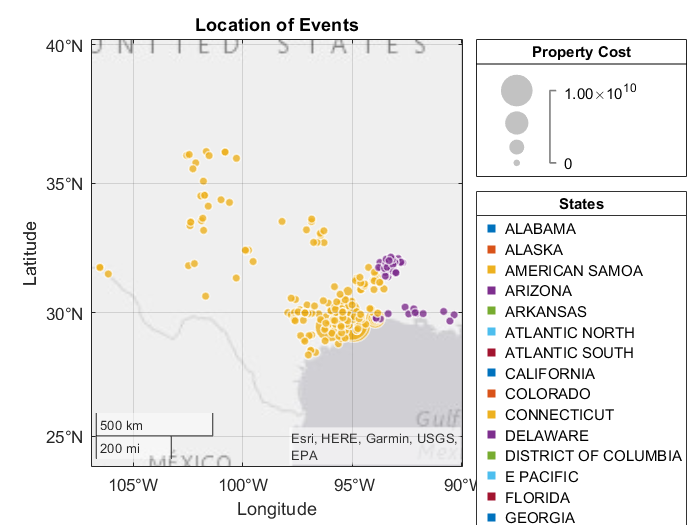

geobubble(MostImpacted.Begin_Lat,MostImpacted.Begin_Lon,MostImpacted.Property_Cost,MostImpacted.State,"Visible","on","SizeLegendTitle","Property Cost","ColorLegendTitle","States")
legend show
title('Location of Events')

## Analysis

### Three Counties with Most Events in Texas

In Texas, the three counties that had most events were Harris, Galveston, and Fort Bend.

State1 = MostImpacted(MostImpacted.State == "TEXAS",:);
B = groupsummary(State1,"CZ_Name");
B = sortrows(B,'GroupCount','descend')

B = 95×2 table
     CZ_Name      GroupCount
    __________    __________

    HARRIS            21    
    GALVESTON         17    
    FORT BEND         13    
    ANGELINA          12    
    BRAZORIA          12    
    SABINE            12    
    BASTROP            9    
    CHAMBERS           8    
    CALDWELL           7    
    MONTGOMERY         6    
    CALHOUN            5    
    JEFFERSON          5    
    MATAGORDA          5    
    WHARTON            5    
    FAYETTE            4    
    LIBERTY            4    


### Three Counties with Most Events in Louisiana

In Louisiana, the three counties that had most events were Natchitoches, Sabine, Red River.

State2 = MostImpacted(MostImpacted.State == "LOUISIANA",:);
C = groupsummary(State2,"CZ_Name");
C = sortrows(C,'GroupCount','descend')

C = 30×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    
    WINN                 6    
    CAMERON              4    
    VERMILION            4    
    DE SOTO              3    
    UNION                2    
    ACADIA               1    
    BEAUREGARD           1    
    BIENVILLE            1    
    BOSSIER              1    
    CADDO                1    
    CALCASIEU            1    
    CALDWELL             1    
    CLAIBORNE            1    


### Three Counties with Highest Property Cost in Texas

In Texas, the three counties with highest property cost were Galveston, Fort Bend, and Montgomery. The costs were estimated to be about $20 billion, $16 billion, and $14 billion, respectively.

D = groupsummary(State1,"CZ_Name","sum","Property_Cost");
D = sortrows(D,'sum_Property_Cost','descend')

D = 95×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    GALVESTON           17                2e+10    
    FORT BEND           13           1.6004e+10    
    MONTGOMERY           6              1.4e+10    
    HARRIS              21           1.0001e+10    
    JEFFERSON            5                3e+09    
    BRAZORIA            12           2.0008e+09    
    ARANSAS              2             1.95e+09    
    ORANGE               3              1.5e+09    
    NUECES               2              1.3e+09    
    WALKER               4              1.2e+09    
    LIBERTY              4                1e+09    
    SAN JACINTO          3                7e+08    
    HARDIN               1                6e+08    
    POLK                 2                6e+08    
    SAN PATRICIO         2             5.02e+08   

### Three Counties with Highest Property Cost in Louisiana

In Louisiana, the three counties with highest property cost were Calcasieu, Beauregard, and Acadia. The costs were estimated to be about $60 million, $15 million, and $0.2 million, respectively.

E = groupsummary(State2,"CZ_Name","sum","Property_Cost");
E = sortrows(E,'sum_Property_Cost','descend')

E = 30×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    CALCASIEU           1                6e+07     
    BEAUREGARD          1              1.5e+07     
    ACADIA              1                2e+05     
    CAMERON             4                72000     
    VERMILION           4                 5000     
    BIENVILLE           1                    0     
    BOSSIER             1                    0     
    CADDO               1                    0     
    CALDWELL            1                    0     
    CLAIBORNE           1                    0     
    DE SOTO             3                    0     
    EAST CAMERON        1                    0     
    GRANT               1                    0     
    IBERIA              1                    0     
    JACKSON             1                    0    

## Conclusions and Recommendations

In summary, the major contributing factor to property damage was the floods, as well as winds. Hence, it is reasonable to expect the damage to be higher in coastal areas, and that was supported by our analysis. Thus, it is wise to allocate more resources to coastal areas.

Also, as revealed by statistics, claims adjusters would need more assistance in Texas and Louisiana, especially in the counties identified above. However, it should be noted that counties in Texas showed much higher absolute property cost than counties in Louisiana. 

Additional work is necessary to determine further details needed for a comprehensive plan, such as the specific types of property being damaged.